# MAE 158 Drag Calculator

#### Shashwat Sparsh

#### ID: 21697442

### `Skin Friction Drag Coeff`

#### Setup

hp_aircraft = 1;
T = 400;
%P = 1;  % via Table A.2
R = 1716;
rho = 0.0008754;

speedSound = sqrt(1.4*R*T)

speedSound = 980.2857

V = [230:1:880]     %765;

V =    230   231   232   233   234   235   236   237   238   239   240   241   242   243   244   245   246   247   248   249   250   251   252   253   254   255   256   257   258   259   260   261   262   263   264   265   266   267   268   269   270   271   272   273   274   275   276   277   278   279


M = V/speedSound    % Mach Number

M =     0.2346    0.2356    0.2367    0.2377    0.2387    0.2397    0.2407    0.2418    0.2428    0.2438    0.2448    0.2458    0.2469    0.2479    0.2489    0.2499    0.2509    0.2520    0.2530    0.2540    0.2550    0.2560    0.2571    0.2581    0.2591    0.2601    0.2611    0.2622    0.2632    0.2642    0.2652    0.2662    0.2673    0.2683    0.2693    0.2703    0.2713    0.2724    0.2734    0.2744    0.2754    0.2765    0.2775    0.2785    0.2795    0.2805    0.2816    0.2826    0.2836    0.2846


Sref = 1000;

%CRexp = [];
%K = [];
%Cf = [];
%f = [];

%% Characteristic Lengths
MACexpW = 0;
MACexph = 0;
MACexpv = 0;
Lc = [MACexpW, MACexph, MACexpv, 16.2, 16.8];

%% Ratios
Lf = 119;
Df = 11;
ratios = [0.12, 0.09, 0.09, 0.06, Lf/Df, 5]  % Thickness and Fineness

ratios =     0.1200    0.0900    0.0900    0.0600   10.8182    5.0000


sigma = [0.2, 0.35, 0.8, 1] % Taper

sigma =     0.2000    0.3500    0.8000    1.0000



%% Sexp
Sexpw = 0;  % Defined Later on
Sexp = [Sexpw, 261, 161]

Sexp =      0   261   161



%% Swet
Swet = [0, 0, 0, 117, 0, 455]

Swet =      0     0     0   117     0   455


#### Wing

bW = 93.2;                      % Span
tcW = 0.18;
sweepangleW = 28;               % Sweep Angle
sigmaW = 0.2;                   % Taper Ratio: cT/cR
CRW = 17.8;                     % Root Chord
Coverage_wing = .17;            % Percent Covered
Rfuse = 11/2;

% Getting Swet %
SexpW = (1-Coverage_wing)*Sref;
SwetW = SWET(SexpW);

% Getting Skin Friction Coefficient %
CTW = sigmaW * CRW;
CRexp_wing = CREXP(CRW, CTW, Rfuse, bW);
MACexpW = MAC(CRexp_wing,CTW);
 
RNw = ReynoldsNumber(V, MACexpW);
Cf_w = CF(RNw);

% Getting Form Factor %
Kwing = Kairfoil(tcW, M, sweepangleW);

% Calculating f and adding to array %
fwing = F(Kwing, Cf_w, SwetW);

#### Horizontal Tail

SexpH = 261;
tcH = 0.09;
sweepangleH = 31.6;             % Sweep Angle
sigmaH = 0.35;                  % Wing Taper Ratio
CRH = 11.1;                     % Root Chord

% Getting Swet %
SwetH = SWET(SexpH);

% Getting Skin Friction Coefficient %
CTH = sigmaH * CRH;
MACexpH = MAC(CRH,CTH);
 
RNh = ReynoldsNumber(V, MACexpH);
Cf_h = CF(RNh);

% Getting Form Factor %
Khoriztail = Kairfoil(tcH, M, sweepangleH);

% Calculating f and adding to array %
fhoriztail = F(Khoriztail, Cf_h, SwetH);

#### Vertical Tail

SexpV = 161;
tcV = 0.09;
sweepangleV = 43.5;             % Sweep Angle 
sigmaV = 0.8;                   % Wing Taper Ratio
CRV = 15.5;                     % Root Chord

% Getting Swet %
SwetV = SWET(SexpV);

% Getting Skin Friction Coefficient %
CTV = sigmaV * CRV;
MACexpV = MAC(CRV,CTV);
 
RNv = ReynoldsNumber(V, MACexpV);
Cf_v = CF(RNv);

% Getting Form Factor %
Kverttail = Kairfoil(tcV, M, sweepangleV);

% Calculating f and adding to array %
fverttail = F(Kverttail, Cf_v, SwetV);

#### Pylons

SwetP = 117;                    % Wetted Area
tcP = 0.06;
sweepangleP = 0;                % Sweep Angle
sigmaP = 1;                     % Taper Ratio: cT/cR
chordP = 16.2;                  % Chord

% Getting Skin Friction Coefficient %
RNp = ReynoldsNumber(V, chordP);
Cf_p = CF(RNp);

% Getting Form Factor %
Kpylon = Kairfoil(tcP, M, sweepangleP);

% Calculating f and adding to array %
fpylon = F(Kpylon, Cf_p, SwetP);

#### Fuselage

Lf = 105;
Df = 11;

% Calculating Swet %
SwetF = 0.8 * pi * Df * Lf;

% Getting Skin Friction Coefficient %
RNf = ReynoldsNumber(V, Lf);
Cf_f = CF(RNf);

% Getting Form Factor %
ratioF = Lf/Df;
Kfuse = KFR(ratioF);           % Via Digitized Figure 11.4

% Calculating f and adding to array %
ffuselage = F(Kfuse, Cf_f, SwetF);

#### Nacelles

% Swet %
SwetN = 455;

% Getting Skin Friction Coefficient %
Ln = 16.8;
RNn = ReynoldsNumber(V, 16.8);
Cf_n = CF(RNn);

% Getting Form Factor %
ratioN = 5;
Knacelle = KFR(ratioN);           % Via Digitized Figure 11.4

% Calculating f and adding to array %
fnacelle = F(Knacelle, Cf_n, SwetN);

#### Total Skin Friction

ftotal = fwing + fhoriztail + fverttail + fpylon + ffuselage + fnacelle;
CDP_total = ftotal./Sref;

### `Induced Drag Coeff`

% Getting CL %
W = 98000;              % Aircraft Weight
q = 0.5 * rho * (V.^2);  % Dynamic Pressure
CL = W ./ (q * Sref);     % Coeff of Lift
% Getting Aspect Ratio %
ARw = (bW^2)/Sref;
% Getting CDi %
efactor = oswaldEff(ARw, CDP_total);        % Oswald Efficiency Factor


e =

     []



e = 1;                                      % Ignore
CDi = (CL.^2) ./ ((pi * ARw) .* efactor);   % Coeff of Induced Drag

## `Total Drag & Lift/Drag Ratio`

ProfileDrag = CDP_total .* q .* Sref

ProfileDrag = 	1.0e+03 *

    0.4701    0.4739    0.4777    0.4815    0.4853    0.4892    0.4930    0.4969    0.5007    0.5046    0.5085    0.5124    0.5164    0.5203    0.5243    0.5282    0.5322    0.5362    0.5402    0.5443    0.5483    0.5524    0.5564    0.5605    0.5646    0.5687    0.5728    0.5770    0.5811    0.5853    0.5895    0.5936    0.5978    0.6021    0.6063    0.6105    0.6148    0.6191    0.6234    0.6277    0.6320    0.6363    0.6406    0.6450    0.6494    0.6537    0.6581    0.6626    0.6670    0.6714


InducedDrag = CDi .* q .* Sref

InducedDrag = 	1.0e+04 *

    1.8884    1.8721    1.8560    1.8401    1.8244    1.8089    1.7936    1.7785    1.7636    1.7489    1.7343    1.7200    1.7058    1.6918    1.6779    1.6643    1.6508    1.6374    1.6242    1.6112    1.5984    1.5856    1.5731    1.5607    1.5484    1.5363    1.5243    1.5125    1.5008    1.4892    1.4778    1.4665    1.4553    1.4442    1.4333    1.4225    1.4119    1.4013    1.3909    1.3805    1.3703    1.3602    1.3503    1.3404    1.3306    1.3210    1.3114    1.3019    1.2926    1.2834


CDtotal = CDP_total + CDi

CDtotal =     0.8359    0.8218    0.8081    0.7946    0.7815    0.7686    0.7560    0.7436    0.7315    0.7197    0.7081    0.6967    0.6856    0.6747    0.6640    0.6536    0.6433    0.6333    0.6234    0.6138    0.6043    0.5950    0.5860    0.5771    0.5683    0.5598    0.5514    0.5431    0.5351    0.5271    0.5194    0.5117    0.5043    0.4969    0.4897    0.4827    0.4757    0.4689    0.4623    0.4557    0.4493    0.4430    0.4368    0.4307    0.4247    0.4188    0.4131    0.4074    0.4018    0.3964


TotalDrag = CDtotal .* q .* Sref

TotalDrag = 	1.0e+04 *

    1.9354    1.9195    1.9038    1.8883    1.8729    1.8578    1.8429    1.8282    1.8137    1.7993    1.7852    1.7712    1.7574    1.7438    1.7304    1.7171    1.7040    1.6910    1.6783    1.6656    1.6532    1.6409    1.6287    1.6167    1.6049    1.5932    1.5816    1.5702    1.5589    1.5477    1.5367    1.5258    1.5151    1.5045    1.4940    1.4836    1.4733    1.4632    1.4532    1.4433    1.4335    1.4239    1.4143    1.4049    1.3956    1.3863    1.3772    1.3682    1.3593    1.3505


L = W;
LiftToDrag = L ./ TotalDrag

LiftToDrag =     5.0635    5.1055    5.1477    5.1900    5.2324    5.2750    5.3177    5.3605    5.4034    5.4465    5.4896    5.5329    5.5764    5.6199    5.6636    5.7073    5.7512    5.7952    5.8394    5.8836    5.9279    5.9724    6.0170    6.0616    6.1064    6.1513    6.1963    6.2414    6.2866    6.3318    6.3772    6.4227    6.4683    6.5140    6.5598    6.6056    6.6516    6.6976    6.7437    6.7900    6.8363    6.8827    6.9291    6.9757    7.0223    7.0690    7.1158    7.1627    7.2096    7.2566


[LiftToDragMax, index] = max(LiftToDrag);
Voptimum = V(index)

Voptimum = 612

## `Plots`

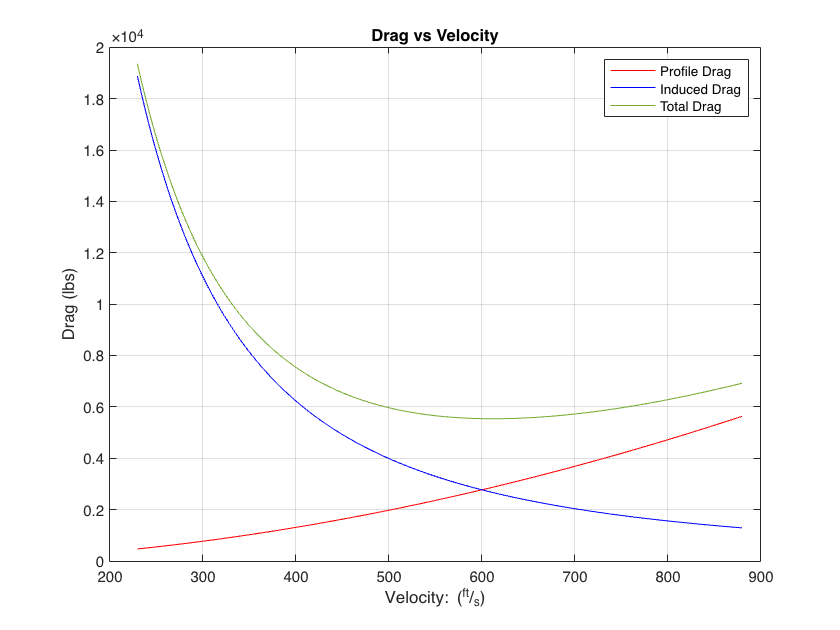

plot(V, ProfileDrag, 'r', V, InducedDrag, 'b')
hold on;
plot(V, TotalDrag, Color=[0.4660 0.6740 0.1880])
grid on
title("Drag vs Velocity")
ylabel("Drag (lbs)")
xlabel("Velocity: (^{ft}/_{s})")
legend("Profile Drag", "Induced Drag", "Total Drag")
hold off

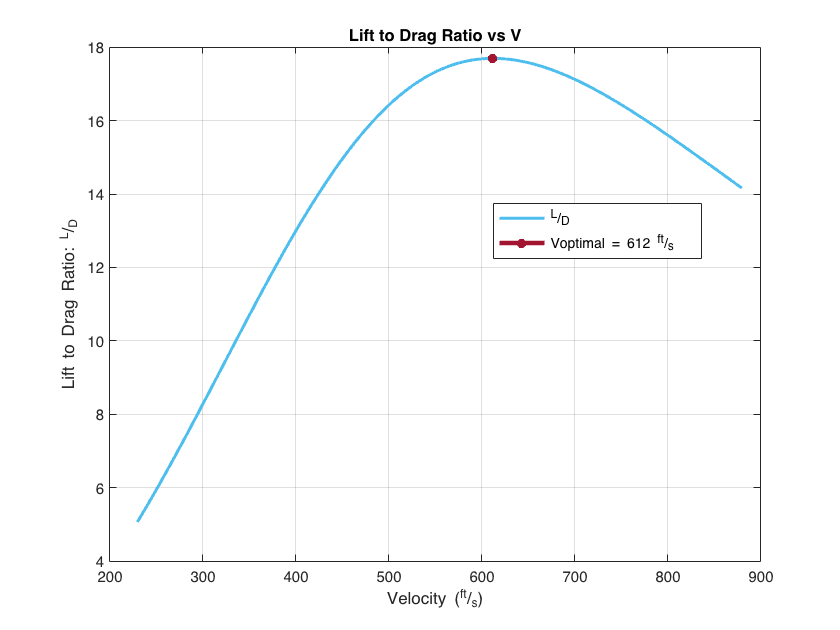

plot(V,LiftToDrag, Color=[0.3010 0.7450 0.9330], LineWidth=2)
hold on
%plot(Voptimum, LiftToDragMax, 'Color', 'r', 'Marker','o', 'LineWidth',1)
plot(Voptimum, LiftToDragMax, Color=[0.6350 0.0780 0.1840], Marker="*", LineWidth=3);
grid on
title("Lift to Drag Ratio vs V")
ylabel("Lift to Drag Ratio: ^{L}/_{D}")
xlabel("Velocity (^{ft}/_{s})")
legend("^{L}/_{D}","Voptimal = 612 ^{ft}/_{s}",Location="best")
%dim = [.2 .5 .3 .3];
%str = 'Voptimal = ';
%annotation('textbox',dim,'String',str,'FitBoxToText','on');
hold off;

## `Functions`

#### Reynolds Number Function

function RN = ReynoldsNumber(Velocity, characteristicLength)
    mu = 3.025E-7;
    rho = 0.0008754;
    V = Velocity;
    Lc = characteristicLength;
    RN = (rho * V * Lc)/mu;
end

#### Swet Function

function Swet = SWET(Sexp)
    Swet = 2 * 1.02 * Sexp;
end

#### MAC Function

function cbar = MAC(cR, cT)
    cbar= (2/3) * (cR + cT - ((cR*cT)/(cR+cT)));
end

#### CR Exposed Function

function crexp = CREXP(cR, cT, y, b)
    crexp = cR - ((cR- cT)*(2*(y/b)));
end

#### Skin Friction Coefficient

function Cf = CF(RN)
    Cf = 0.455 ./ ((log10(RN)).^2.58);
end

#### Form Factor for Airfoils

function K = Kairfoil(tc, Mo, sweepAngle)
    numTerm = (2-Mo.^2) * cosd(sweepAngle);
    denTerm = sqrt(1-(Mo*cosd(sweepAngle)^2));
    Z = numTerm/denTerm;
    K = 1 + (Z * tc) + (100*tc^4);
end

#### Form Factor via Fineness Ratio

function K = KFR(LbyD)
    K = 1.991*LbyD^-1.024+0.9084;
    % General model Power2:
    % Coefficients (with 95% confidence bounds):
    %    a =       1.991  (1.882, 2.101)
    %    b =      -1.024  (-1.091, -0.9582)
    %    c =      0.9084  (0.8888, 0.9279)
end

#### F Function

function f = F(K, Cf, Swet)
    f = K * Cf * Swet;
end

#### Oswald Efficiency Function

function e = oswaldEff(ARW, CDP)
    e = []
    for N = 1:length(CDP)
        CDProunded = round(CDP(N),2);   % Skips Interpolation
        switch CDProunded
            case .01
                e = [e, .000114*ARW^2 - .01085*ARW + .9659];                        % e vs ARw, CDP = .01
            case .015
                e = [e, (2.5e-05)*ARW^3 - .0002244*ARW^2 - .01422*ARW + .9649];     % e vs ARw, CDP = .015
            case  .02
                e = [e, .000364*ARW^2 - .02149*ARW + .9641];                        % e vs ARw, CDP = .02
            case .025
                e = [e, (-6.849e-06)*ARW^3 + .0006443*ARW^2 - .0269*ARW + .9614];   % e vs ARw, CDP = .025
        end
    end
end

%% Digitized Curved Results for Oswald Efficiency Factor %%
%{
    CDP = .01
    f(x) = p1*x^2 + p2*x + p3
    Coefficients (with 95% confidence bounds):
        p1 =    0.000114  (0.000103, 0.0001251)       
        p2 =    -0.01085  (-0.01099, -0.01071)       
        p3 =      0.9659  (0.9655, 0.9663)
%}
%{
    CDP = .015
    f(x) = p1*x^3 + p2*x^2 + p3*x + p4
    Coefficients (with 95% confidence bounds):       
        p1 =     2.5e-05  (1.971e-05, 3.03e-05)       
        p2 =  -0.0002244  (-0.0003207, -0.0001281)       
        p3 =    -0.01422  (-0.01471, -0.01373)       
        p4 =      0.9649  (0.9642, 0.9655)
%}
%{
    CDP = .02
    f(x) = p1*x^2 + p2*x + p3
    Coefficients (with 95% confidence bounds):       
        p1 =    0.000364  (0.0003456, 0.0003824)       
        p2 =    -0.02149  (-0.02171, -0.02126)       
        p3 =      0.9641  (0.9635, 0.9647)
%}
%{
    CDP = .025
    f(x) = p1*x^3 + p2*x^2 + p3*x + p4
    Coefficients (with 95% confidence bounds):       
        p1 =  -6.849e-06  (-1.049e-05, -3.207e-06)       
        p2 =   0.0006443  (0.0005786, 0.0007101)       
        p3 =     -0.0269  (-0.02723, -0.02656)       
        p4 =      0.9614  (0.961, 0.9619)
%}
